## Load data

% Cortical amygdala
coa15 = load('coa_15_2_2.mat'); %15 odors
coaAA = load('coa_AAmix_2_2.mat'); %aversive&appetitive&mixtures
coaCS = load('coa_CS_2_2.mat'); %concentration series
coa151 = load('coa_15_2_1.mat');
coaAA1 = load('coa_AAmix_2_1.mat');
coaCS1 = load('coa_CS_2_1.mat');

% Piriform cortex
pcx15 = load('pcx_15_2_2.mat');
pcxAA = load('pcx_AAmix_2_2.mat');
pcxCS = load('pcx_CS_2_2.mat');
pcx151 = load('pcx_15_2_1.mat');
pcxAA1 = load('pcx_AAmix_2_1.mat');
pcxCS1 = load('pcx_CS_2_1.mat');

% Number of odors
odors15 = 1:15; 
odorsAA = 1:10; 
% Colors
coaC = [227,26,28] ./ 255;
pcxC = [82,82,82]./255;
labelC = [37,37,37] ./ 255;

## Compute some basic stuff

## Number of units

idxU = 0;
coaUnits = {coa15.esp, coaAA.esp, coaCS.esp};
for idx = 1:3
    esp = coaUnits{idx};
    for idxExp = 1:length(esp)
        for idxShank = 1:4
            for idxUnit = 1:length((esp(idxExp).shankNowarp(idxShank).cell));
                if esp(idxExp).shankNowarp(idxShank).cell(idxUnit).good == 1
                    idxU = idxU + 1;
                end
            end
        end
    end
end
coaCells = idxU;
disp('Units from plCoA:')

Units from plCoA:


coaCells

coaCells = 647


idxU = 0;
pcxUnits = {pcx15.esp, pcxAA.esp, pcxCS.esp};
for idx = 1:3
    esp = pcxUnits{idx};
    for idxExp = 1:length(esp)
        for idxShank = 1:4
            for idxUnit = 1:length((esp(idxExp).shankNowarp(idxShank).cell));
                if esp(idxExp).shankNowarp(idxShank).cell(idxUnit).good == 1
                    idxU = idxU + 1;
                end
            end
        end
    end
end
pcxCells = idxU;
disp('Units from aPC:')

Units from aPC:


pcxCells

pcxCells = 592

## **Extract baseline firing, change of spike counts, Fano factor and auROC - 1000 ms**

Mcoa15 = find_Baseline_DeltaRsp_FanoFactor(coa15.esp, odors15, 1000);
McoaAA = find_Baseline_DeltaRsp_FanoFactor(coaAA.esp, odors15, 1000);
Mpcx15 = find_Baseline_DeltaRsp_FanoFactor(pcx15.esp, odors15, 1000);
MpcxAA = find_Baseline_DeltaRsp_FanoFactor(pcxAA.esp, odors15, 1000);
McoaCS = find_Baseline_DeltaRsp_FanoFactor(coaCS.esp, odors15, 1000);
MpcxCS = find_Baseline_DeltaRsp_FanoFactor(pcxCS.esp, odors15, 1000);
logSignificantCoa = [Mcoa15.significance; McoaAA.significance];
logSignificantCoa = logSignificantCoa(:);
logSignificantPcx = [Mpcx15.significance; MpcxAA.significance];
logSignificantPcx = logSignificantPcx(:);

## Figure 1B

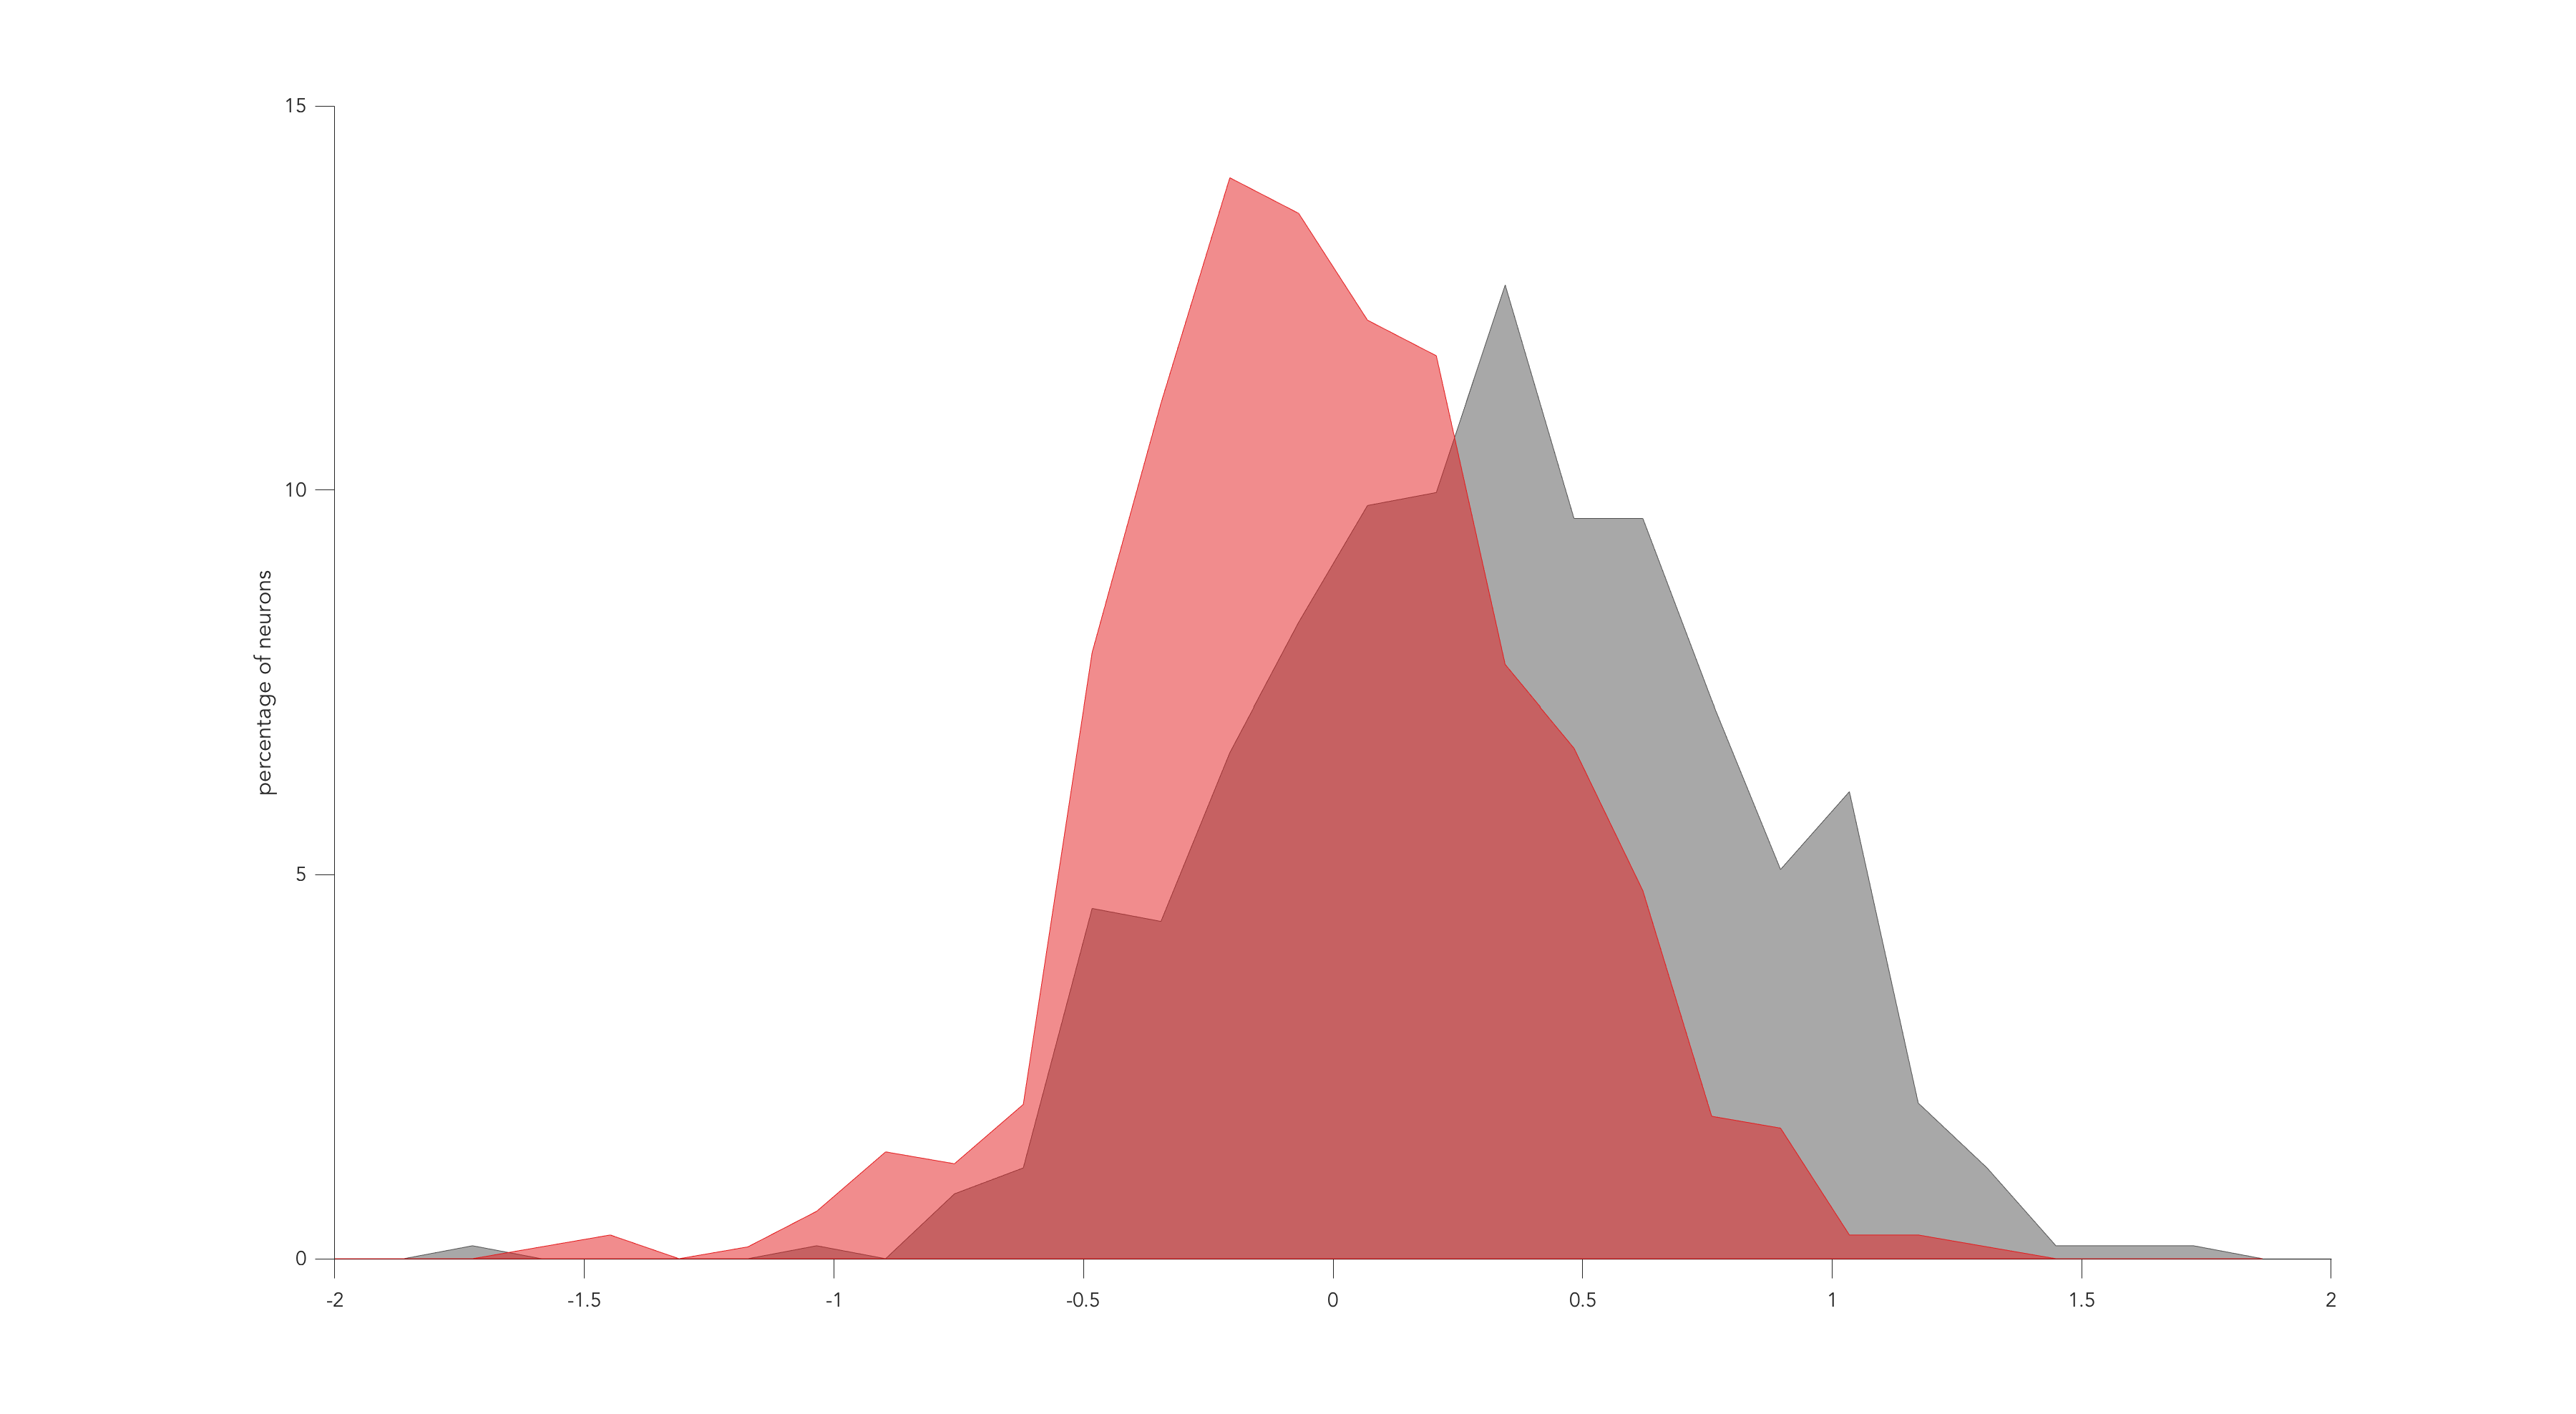

%%
bslCOA = [Mcoa15.Bsl';McoaAA.Bsl'; McoaCS.Bsl'];
bslPCX = [Mpcx15.Bsl';MpcxAA.Bsl';MpcxCS.Bsl'];
logSignificantCoa = [Mcoa15.significance; McoaAA.significance; McoaCS.significance];
logSignificantPcx = [Mpcx15.significance; MpcxAA.significance; MpcxCS.significance];

bslCOAsigE = [];
bslCOAsigI = [];
for cCoa = 1:size(logSignificantCoa,1)
    appE = find(logSignificantCoa(cCoa,:)>0);
    appI = find(logSignificantCoa(cCoa,:)<0);
    if numel(appE) > 0
        bslCOAsigE = [bslCOAsigE, bslCOA(cCoa)];
    end
    if numel(appI) > 0
        bslCOAsigI = [bslCOAsigI, bslCOA(cCoa)];
    end
end

bslPCXsigE = [];
bslPCXsigI = [];
for cPcx = 1:size(logSignificantPcx,1)
    appE = find(logSignificantPcx(cPcx,:)>0);
    appI = find(logSignificantPcx(cPcx,:)<0);
    if numel(appE) > 0
        bslPCXsigE = [bslPCXsigE, bslPCX(cPcx)];
    end
    if numel(appI) > 0
        bslPCXsigI = [bslPCXsigI, bslPCX(cPcx)];
    end
end

maxBsl = max(bslCOA);
minBsl = min(bslPCX);
edges = logspace(-2,2,30);
[N1,edges] = histcounts(bslCOA, edges);
[N2,edges] = histcounts(bslPCX, edges);
N1 = N1 ./ numel(bslCOA);
N2 = N2 ./ numel(bslPCX);

edges = log10(edges(1:end-1));

figure
set(gcf,'color','white', 'PaperPositionMode', 'auto');
set(gcf,'Position',[109 69 1800 988]);
h1 = area(edges, N2*100);
h1.FaceColor = pcxC;
h1.EdgeColor = pcxC;
alpha(h1, 0.5)
hold on; 
h2 = area(edges, N1*100);
h2.FaceColor = coaC;
h2.EdgeColor = coaC;
alpha(h2, 0.5)
ylabel('percentage of neurons')
set(gca, 'box', 'off', 'tickDir', 'out', 'fontname', 'avenir', 'fontsize', 14)


p = ranksum(bslCOA, bslPCX);
median_plCoA = median(bslCOA)

median_plCoA = 1.0800

median_aPC = median(bslPCX)

median_aPC = 2.4900

p_Value = p

p_Value = 0

Figure 1C

DeltaRspCOA = [Mcoa15.DeltaRsp;McoaAA.DeltaRsp];
DeltaRspPCX = [Mpcx15.DeltaRsp;MpcxAA.DeltaRsp];


xMargin = 0.05 * range([DeltaRspCOA(:); DeltaRspPCX(:)]);
bottomMargin = 0;
topMargin = 0.001;
leftX = min([DeltaRspCOA(:); DeltaRspPCX(:)]);
rightX = max([DeltaRspCOA(:); DeltaRspPCX(:)]);
blankFigure([leftX-xMargin rightX+xMargin 0-bottomMargin 0.2+topMargin]);

distributionPlot(DeltaRspCOA(:),'histOri','right','color',coaC,'widthDiv',[2 2],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')

ans =    1.0e+04 *

    0.0000         0         0         0         0         0    0.0000    0.0000    0.0011    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0006    0.0000    0.0000    0.0000    0.0000    0.0012    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0020    0.0031    0.0003    0.0000    0.0000    0.0001    0.0089    0.0522    0.0149    0.0001    0.0000    0.0000    0.0489    1.2164    1.0821    0.0386    0.0000


distributionPlot(DeltaRspPCX(:),'histOri','left','color',pcxC,'widthDiv',[2 1],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')

ans =    1.0e+04 *

    0.0000         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0000    0.0000    0.0002    0.0005    0.0000    0.0000    0.0011    0.0011    0.0000    0.0000    0.0049    0.0008    0.0000    0.0000    0.0199    0.0024    0.0000    0.0007    0.0800    0.0027    0.0000    0.0082    0.3894    0.0051    0.0000    0.1395    3.0023    0.0247    0.0000    0.2192    0.7006    0.0007    0.0000    0.0895    0.1237    0.0000


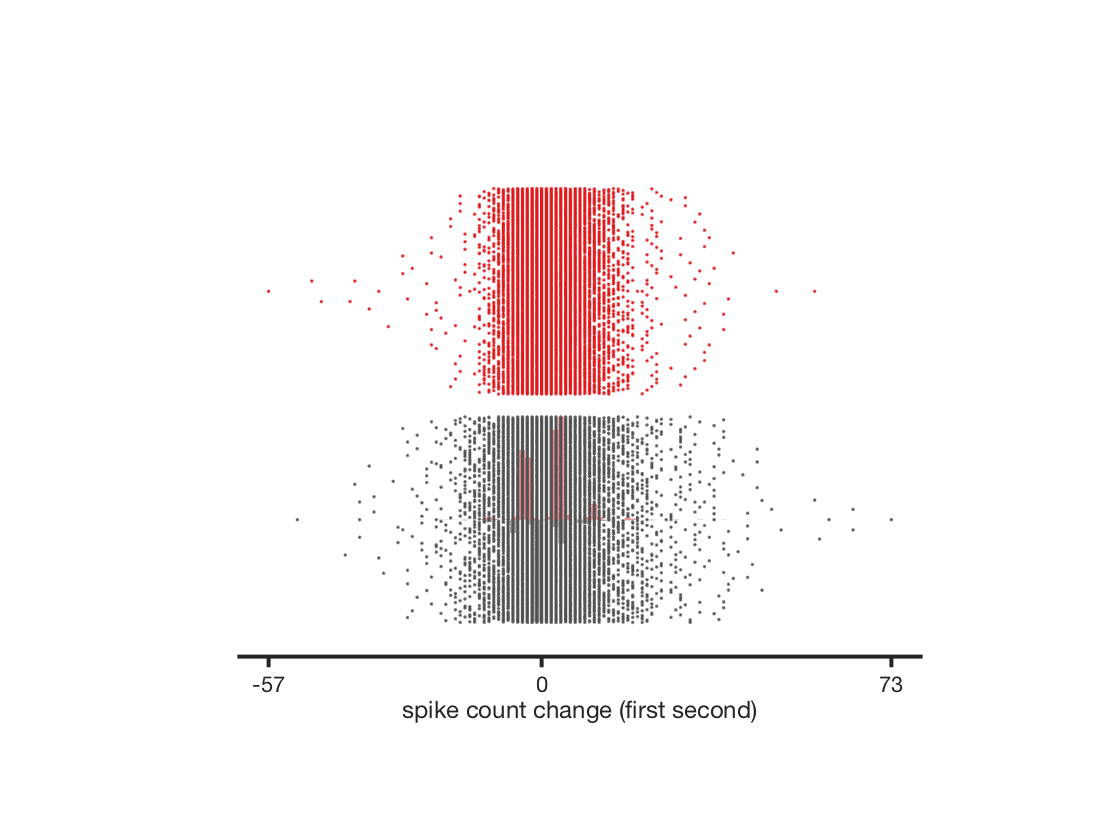

hold on
coaRsp = DeltaRspCOA;
coaRsp(logSignificantCoa == 0) = [];
pcxRsp = DeltaRspPCX;
pcxRsp(logSignificantPcx == 0) = [];
dataToPlot = {pcxRsp,coaRsp};
catIdx = [ones(length(pcxRsp),1); zeros(length(coaRsp),1)];
colori = {coaC, pcxC};
plotSpread(dataToPlot,'categoryIdx',catIdx,'categoryColors', colori, 'showMM', 0, 'xyOri', 'flipped')
alpha(0.5)

clear axP
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axP.lineThickness = 2;
axP.axisLabel = 'spike count change (first second)';
axP.axisOrientation = 'h';
axP.tickLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabels = {num2str(floor(leftX)), num2str(0), num2str(ceil(rightX))};
axP.axisOffset = 0.4;
axP.fontSize = 12; 
axP.color = labelC; 
AxisMMC(start, fin, axP);


medianRspCoa = median(coaRsp)

medianRspCoa = 0

medianRspPcx = median(pcxRsp)

medianRspPcx = 0

p = ranksum(coaRsp, pcxRsp)

p = 0.1808

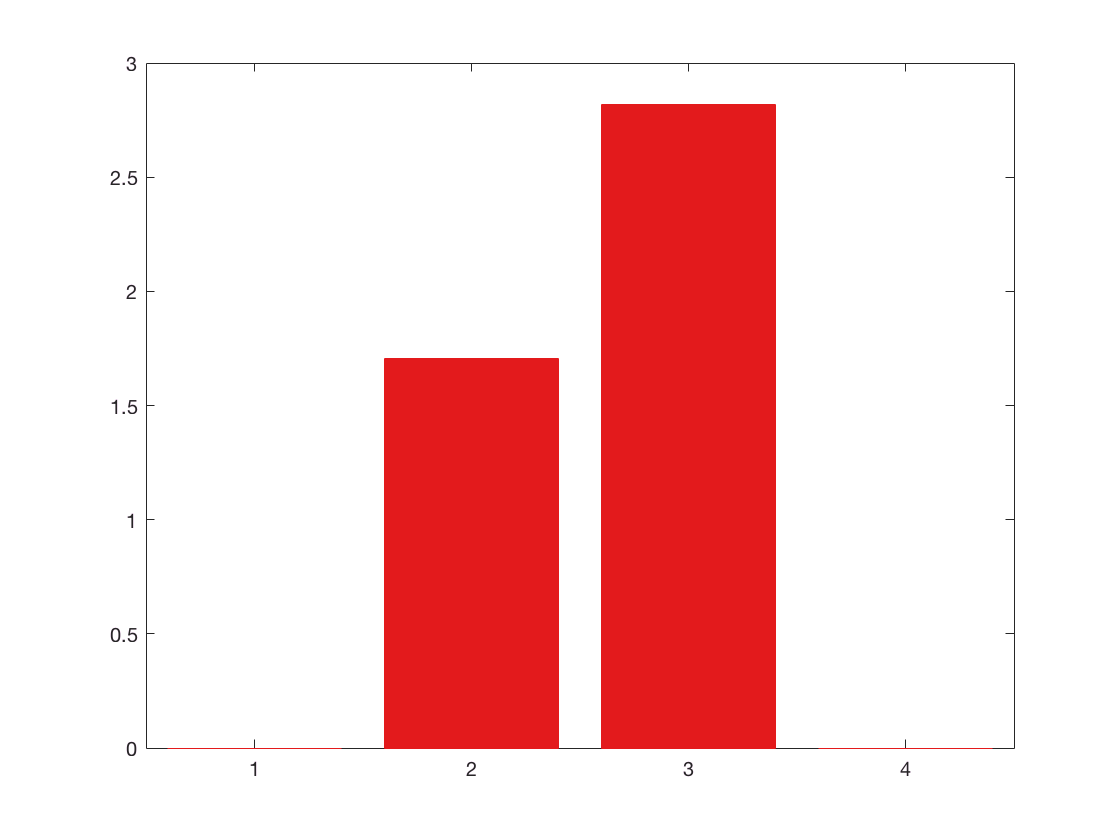

%%
meanBslEICoa = [mean(bslCOAsigE) mean(bslCOAsigI)];
meanBslEIPcx = [mean(bslPCXsigE) mean(bslPCXsigI)];

figure
bar([0 meanBslEICoa 0], 'FaceColor', coaC, 'EdgeColor', coaC)

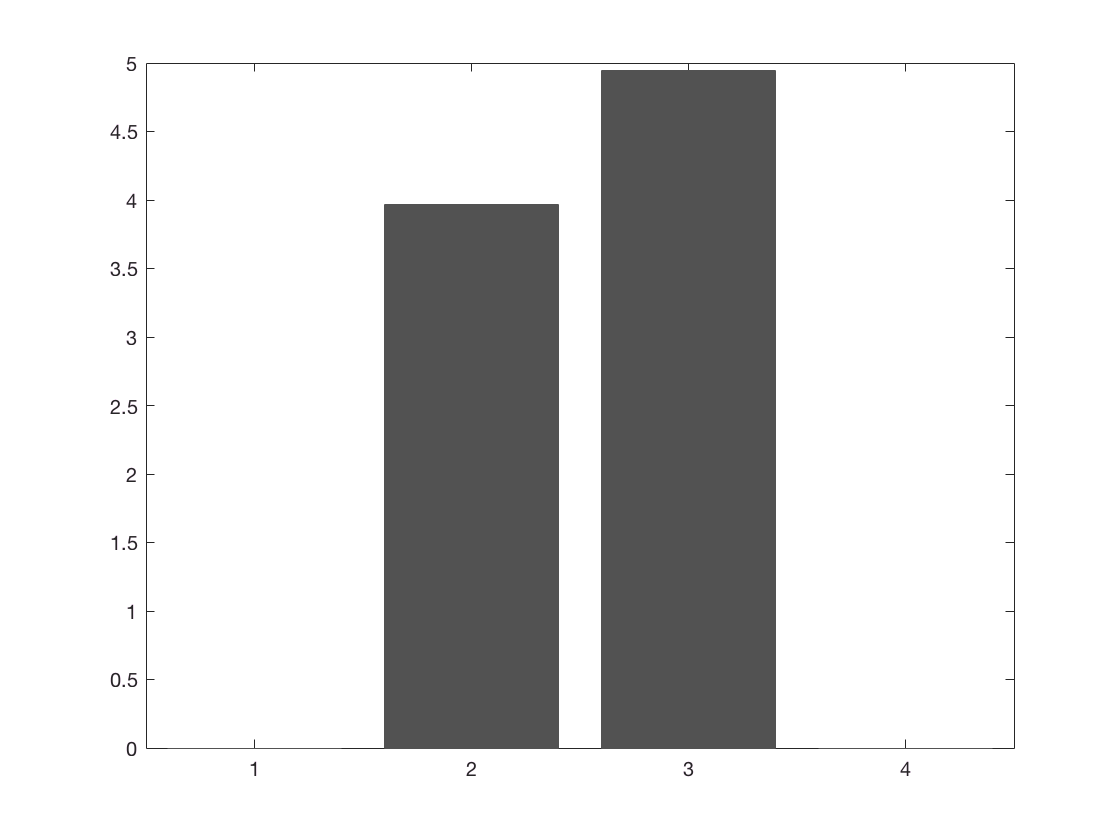

figure
bar([0 meanBslEIPcx 0], 'FaceColor', pcxC, 'EdgeColor', pcxC)